## 前進動作における真値とオドメトリの比較

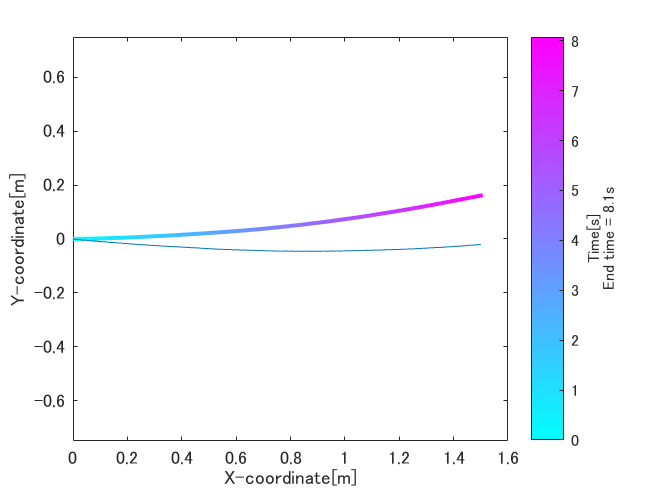

csvFilePath = 'forward_roomba_data.csv';
dataMatrix = readmatrix(csvFilePath);

csvFilePath2 = 'forward_motioncap_data.csv';
dataMatrix4 = readmatrix(csvFilePath2);

time = dataMatrix(:,1)/1000;  % 時間 [s]
time = time - time(1);
theta = dataMatrix(:,4);     % theta
x = dataMatrix(:,2);     % x座標
y = dataMatrix(:,3);     % y座標


true_x = dataMatrix4(:,2);
true_y = dataMatrix4(:,3);
true_y = true_y - true_y(1,1);


% プロット設定
figure;
ax = gca;
hold(ax, 'on');
box on;

colormap('cool');
c = colormap;
color_steps = size(c, 1);

%プロット
for i = 1:length(time)-1
    color_index = round((i-1)/(length(time)-1) * (color_steps-1)) + 1;
    line_color = c(color_index, :);
    
    plot(ax, [x(i), x(i+1)], [y(i), y(i+1)], 'Color', line_color, 'LineWidth', 2);
end

plot(ax, true_x,true_y)

% 軸ラベルなどの設定
ylim(ax,[-0.75,0.75]);
xlabel(ax, 'X-coordinate[m]');
ylabel(ax, 'Y-coordinate[m]');

% カラーバーの表示
clim(ax, [min(time), max(time)]);
hcb = colorbar;
xlabel(hcb, {'Time[s]',['End time = ',num2str(round(max(time),1)),'s']});

hold(ax, 'off');

## 旋回動作における真値とオドメトリの比較

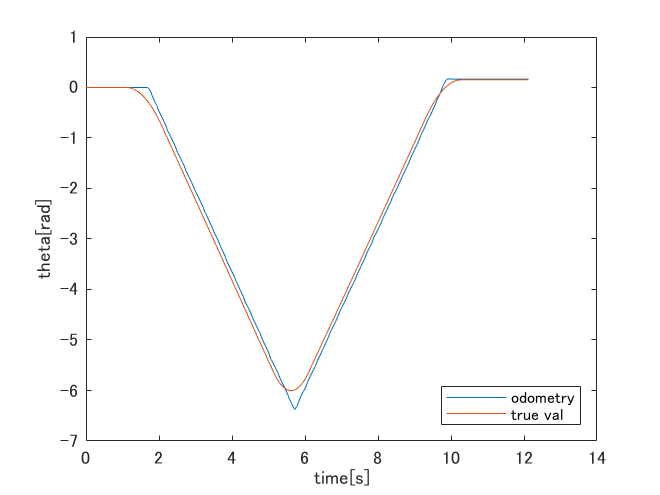

csvFilePath3 = 'turn_roomba_data.csv';
dataMatrix3 = readmatrix(csvFilePath3);

csvFilePath4 = 'turn_motioncap_data.csv';
dataMatrix4 = readmatrix(csvFilePath4);

time = dataMatrix3(:,1)/1000;  % 時間 [s]
time = time - time(1);
theta = dataMatrix3(:,4);     % theta

true_time = dataMatrix4(:,1);
true_time = true_time - true_time(1,1);
true_theta = dataMatrix4(:,4);

% プロット設定
figure;
ax = gca;
hold(ax, 'on');
box on;

plot(ax, time,theta,'DisplayName','odometry')
plot(ax, true_time,true_theta,'DisplayName','true val')
legend('Location','southeast');

% 軸ラベルなどの設定
xlabel(ax, 'time[s]');
ylabel(ax, 'theta[rad]');
hold(ax, 'off');